# Comparing GLM results with standardized betas

with the effect magnitude of stimulus intensity = 1

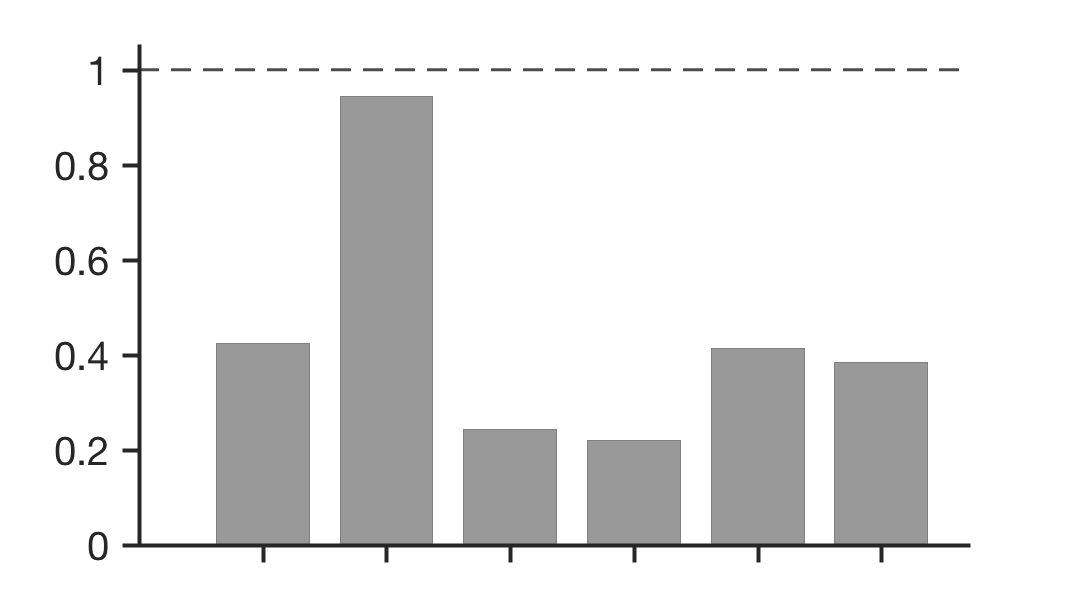

figdir = '/Users/clinpsywoo/github/CRB_project/MWW_inprep/figures';

cols = lines(2);

a = [5.0100    5.5000    2.5000    2.7800    1.5000    2.2700
    2.1200    5.1900    0.6100    0.6100    0.6200    0.8700
    1.4400    4.7700    0.7000    0.7200    1.0900    1.2400
    2.8000    5.6200    0.5100    0.4900    0.1400    0.5000];

close all;
b = a(1:2,:);
y = b(2,:)./b(1,:);
h = bar(y', 'facecolor', [.6 .6 .6], 'edgecolor', [.5 .5 .5]);
h.BarWidth = .75;
h.BaseLine.LineWidth = 1.5;

line([0 6.7], [1 1], 'color', [.3 .3 .3], 'linewidth', 1.5, 'linestyle', '--');

set(gcf, 'Position', [2        1039         535         306], 'color', 'w');
set(gca, 'box', 'off', 'fontsize', 20, 'xlim', [0 6.7], 'ylim', [0 1.05], ...
    'tickdir', 'out', 'ticklength', [.02 .02], 'linewidth', 2, 'xticklabel', '');


savename = fullfile(figdir, 'relative_beta_coefficients_all.pdf');
pagesetup(gcf);
saveas(gcf, savename);

pagesetup(gcf);
saveas(gcf, savename);

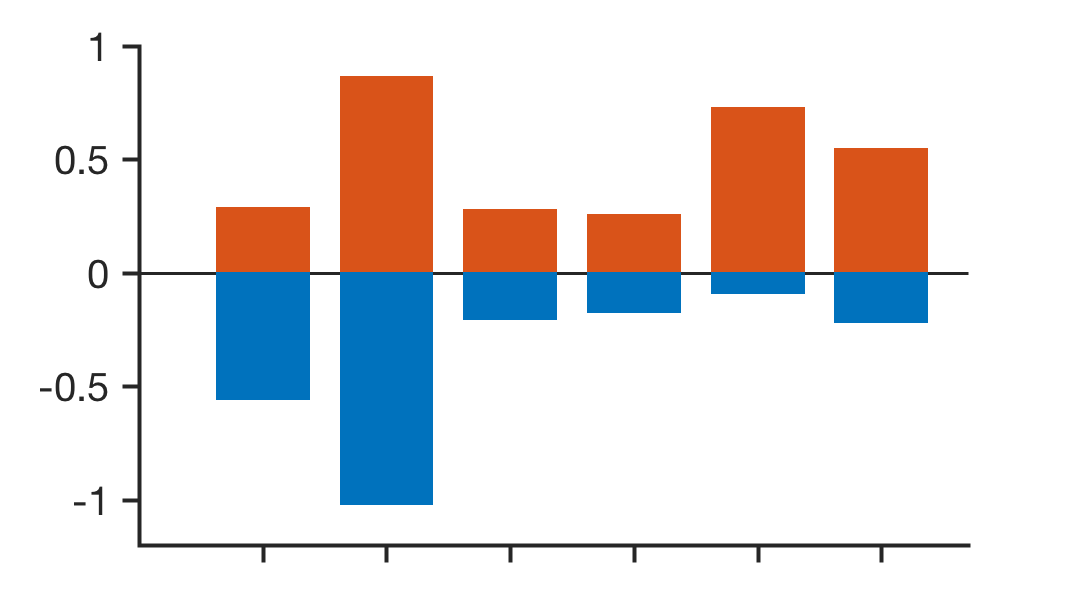

close all;
% bar(fliplr(y'), 'stacked');
y = a(3:4,:)./a(1,:);
h1 = bar(y(1,:)', 'facecolor', cols(2,:), 'edgecolor', cols(2,:));
h1.BarWidth = .75;
h1.BaseLine.LineWidth = 1.5;

hold on;
h2 = bar(-y(2,:)', 'facecolor', cols(1,:), 'edgecolor', cols(1,:));
h2.BarWidth = .75;
h1.BaseLine.LineWidth = 1.5;

% line([0 6.7], [.5 .5], 'color', [.3 .3 .3], 'linewidth', 1.5, 'linestyle', '--');
% line([0 6.7], [-.5 -.5], 'color', [.3 .3 .3], 'linewidth', 1.5, 'linestyle', '--');

set(gcf, 'Position', [2        1039         535         306], 'color', 'w');
set(gca, 'box', 'off', 'fontsize', 20, 'xlim', [0 6.7], 'ylim', [-1.2 1], ...
    'tickdir', 'out', 'ticklength', [.02 .02], 'linewidth', 2, 'xticklabel', '', 'ytick', -1:.5:1);

savename = fullfile(figdir, 'relative_beta_coefficients_pos_neg.pdf');
pagesetup(gcf);
saveas(gcf, savename);

pagesetup(gcf);
saveas(gcf, savename);